# Estructuras de datos: Tablas

Hasta este punto se hemos trabajado con matrices (las cuales tienen la característica de tener el mismo tipo de dato). Sin embargo, si toda esta información está relacionada y cada fila/columna representa algo, entonces lo ideal sería unir toda esta información para su posterior análisis.

**Figura 1.** Información relacionada entre sí, pero guardada en vectores independientes.

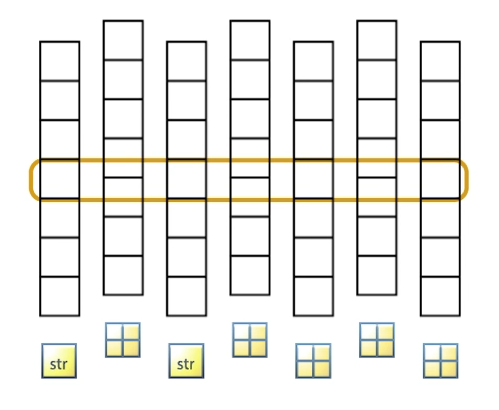

*Tomado de la documentación oficial de MATLAB.*

Una buena alternativa sería unir toda la información en una matriz, pero si la información concatenada no tiene el mismo tipo de dato, entonces obtendríamos un error.

**Figura 2.** Información relacionada entre sí y "guardada" en una matriz.

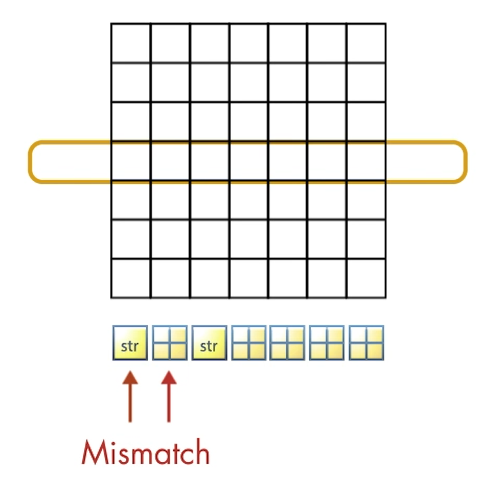

*Tomado de la documentación oficial de MATLAB.*

Por lo tanto, lo ideal sería utilizar una estructura que no tenga estas limitaciones, la cual nos permita unir toda la información a pesar de que hayan columnas de diferente tipo de dato. Esta estructura se conoce como **tabla**.

Las tablas son un tipo de dato adecuado para datos tabulares que a menudo se almacenan como columnas en un archivo de texto o en una hoja de cálculo. Las tablas constan de **observaciones** (filas) y **variables** (columnas).

**Figura 3.** Ilustración de una tabla en MATLAB.

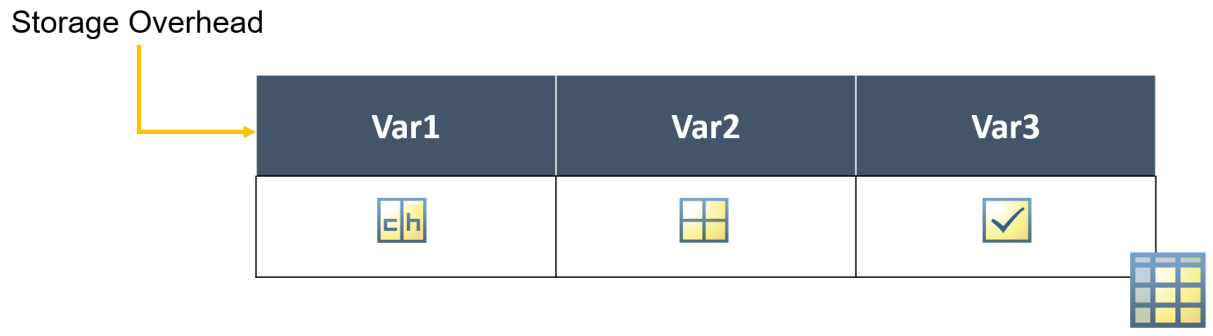

*Tomado de la documentación oficial de MATLAB.*

**Cada variable en una tabla puede tener un tipo de dato diferente del resto de variables. Sin embargo, la única restricción es que cada variable debe tener el mismo número de observaciones.**

Además, no está restringido que una variable sea de una sola columna. Es decir, una variable puede contener varias columnas, siempre y cuando todas estas tengan el mismo número de filas.

Cabe destacar que las tablas (también llamadas *arreglos tabla*) son **contenedores de datos**. Esto es relevante dado que cuando se indexa una tabla es posible extraer una *subtabla* (conjunto reducido de datos de la tabla que sigue siendo una tabla) o es posible extraer directamente el contenido de la tabla.

**Figura 4.** Visualización de un contenedor y el contenido.

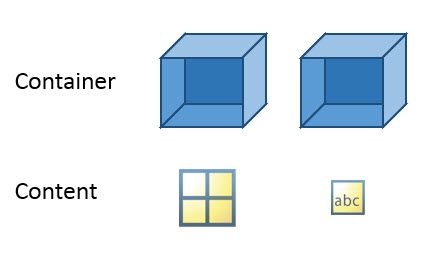

*Tomado de la documentación oficial de MATLAB.*

## Crear una tabla

Las tablas dentro de MATLAB son de clase `table` y se pueden crear de distintas formas, aunque la más usual es ingresando las variables en la función `table`.

### Función `table`

La función `table` permite crear una tabla de distintas formas, pero la más común es ingresando las variables.

**Todas las variables deben tener el mismo número de filas.**


nombres=["rodrigo" "gabriel" "sebastian" ];
edad=[20 22 10];
lugarnac=["lima" "surco" "miraflores"];
sifuma0=logical([0 1 1]);
tablacliente=table(nombres, edad,lugarnac,sifuma0)

tablacliente = 1×4 table
                   nombres                        edad                     lugarnac                       sifuma0      
    _____________________________________    ______________    _________________________________    ___________________

    "rodrigo"    "gabriel"    "sebastian"    20    22    10    "lima"    "surco"    "miraflores"    false  true   true 


nombres=["rodrigo" "gabriel" "sebastian" ]';
edad=[20 22 10]';
lugarnac=["lima" "surco" "miraflores"]';
sifuma0=logical([0 1 1])';

tablacliente=table(nombres, edad,lugarnac,sifuma0)

tablacliente = 3×4 table
      nombres      edad      lugarnac      sifuma0
    ___________    ____    ____________    _______

    "rodrigo"       20     "lima"           false 
    "gabriel"       22     "surco"          true  
    "sebastian"     10     "miraflores"     true  


#### Observación

La visualización de una tabla dentro del live script es muy útil. No obstante, en bastante documentación también se encontrará la visualización de la ventana de comandos (la cual se replica utilizando la función `disp`), por ende se recomienda intentar familiarizarse con ambas formas, no sólo con una.

disp(tablacliente)

      nombres      edad      lugarnac      sifuma0
    ___________    ____    ____________    _______

    "rodrigo"       20     "lima"           false 
    "gabriel"       22     "surco"          true  
    "sebastian"     10     "miraflores"     true  



### Función `array2table`

La función `array2table` permite convertir una matriz en una tabla.

calificaciones=randi(10,10,20)

calificaciones =      5     8     4    10     1    10     6     6    10     4     7     2    10     8     7     8     4     4     1    10
     5     6     8     6     4     5     3     2    10    10     4     5     8    10     1     4     3     8    10     6
    10     5     2     9    10     5     6     2     1     7    10     4     7     2    10     3     9     6     6    10
     4     6     2     1     6     3     2     1     5     4     1     5     5     6     1     3     9     8     7     3
     2     5    10    10     5     2     1     5     9     7     3     6     3     7     6     8     5     3     4     4
     3     7     9    10     5     9     7     5     3     3     9     2     6    10     2     1     1     7     1     7
     7     8    10     6     4     8     7     2     9     6     1    10     3     7     4     7     6     1     9     1
     9     4     9     5    10     6     3     7     9    10     6     7     4     4     9     7     2     9     2     8
    10     1   

calificacioenstablaa=array2table(calificaciones)

calificacioenstablaa =     -2     1     0     1     2     1     5     5     1     0     4    -1     1     1     4     1     0     0     2     1
    -2     5     1     5     0    -2     3    -1     1     1     0    -2     1     1     2     0     3     1     1     5
     1    -2    -1     1     1    -2     5    -1     2     4     1     0     4    -1     1     3     1     5     5     1
     0     5    -1     2     5     3    -1     2    -2     0     2    -2    -2     5     2     3     1     1     4     3
    -1    -2     1     1    -2    -1     2    -2     1     4     3     5     3     4     5     1    -2     3     0     0
     3     4     1     1    -2     1     4    -2     3     3     1    -1     5     1    -1     2     2     4     2     4
     4     1     1     5     0     1     4    -1     1     5     2     1     3     4     0     4     5     2     1     2
     1     0     1    -2     1     5     3     4     1     1     5     4     0     0     1     4    -1     1    -1     1
     1   

## Modificar las propiedades de una tabla

Para modificar las propiedades de una tabla se utiliza la **notación punto**, por lo que conviene explicar esta notación.

La notación punto hace referencia a las variables de la tabla por nombre, `T.varname`, donde `T` es la tabla y `varname` es el nombre de la variable a la cual se accede a través de esta notación (utilizando un punto).

La notación punto se puede utilizar para indexar elementos, añadir o quitar elementos, etc.; pero también se la puede utilizar para acceder a las propiedades de la tabla: `Properties`.

load patients.mat
whos

  Name                            Size            Bytes  Class                             Attributes

  Age                           100x1               800  double                                      
  Diastolic                     100x1               800  double                                      
  Gender                        100x1             11412  cell                                        
  Height                        100x1               800  double                                      
  LastName                      100x1             11616  cell                                        
  Location                      100x1             14208  cell                                        
  SelfAssessedHealthStatus      100x1             11540  cell                                        
  Smoker                        100x1               100  logical                                     
  Systolic                      100x1               800  double                  

patientesTb1=table(LastName, Age, Height, Location)

patientesTb1 = 100×4 table
      LastName      Age    Height              Location           
    ____________    ___    ______    _____________________________

    {'Smith'   }    38       71      {'County General Hospital'  }
    {'Johnson' }    43       69      {'VA Hospital'              }
    {'Williams'}    38       64      {'St. Mary's Medical Center'}
    {'Jones'   }    40       67      {'VA Hospital'              }
    {'Brown'   }    49       64      {'County General Hospital'  }
    {'Davis'   }    46       68      {'St. Mary's Medical Center'}
    {'Miller'  }    33       64      {'VA Hospital'              }
    {'Wilson'  }    40       68      {'VA Hospital'              }
    {'Moore'   }    28       68      {'St. Mary's Medical Center'}
    {'Taylor'  }    31       66      {'County General Hospital'  }
    {'Anderson'}    45       68 

patientesTb1.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'LastName'  'Age'  'Height'  'Location'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


Podemos modificar cualquiera de las propiedades de una tabla accediendo a éstas mediante la notación punto de nuevo. Las propiedades más usuales para modificar son el nombre de las variables, `VariableNames`, y el nombre de las observaciones, `RowNames`.

patientesTb1.Properties.VariableNames=["Apellidos" "Edad" "Altura" "Localidad"]

patientesTb1 = 100×4 table
     Apellidos      Edad    Altura              Localidad          
    ____________    ____    ______    _____________________________

    {'Smith'   }     38       71      {'County General Hospital'  }
    {'Johnson' }     43       69      {'VA Hospital'              }
    {'Williams'}     38       64      {'St. Mary's Medical Center'}
    {'Jones'   }     40       67      {'VA Hospital'              }
    {'Brown'   }     49       64      {'County General Hospital'  }
    {'Davis'   }     46       68      {'St. Mary's Medical Center'}
    {'Miller'  }     33       64      {'VA Hospital'              }
    {'Wilson'  }     40       68      {'VA Hospital'              }
    {'Moore'   }     28       68      {'St. Mary's Medical Center'}
    {'Taylor'  }     31       66      {'County General Hospital'  }
    {'Anderson'}    

## Indexación de tablas

Para detallar la indexación de tablas primero se creará una con el MAT-file "patients.mat" que se encuentra dentro de MATLAB como base de datos de ejemplo.

disp(patientesTb1)

      Apellidos       Edad    Altura              Localidad          
    ______________    ____    ______    _____________________________

    {'Smith'     }     38       71      {'County General Hospital'  }
    {'Johnson'   }     43       69      {'VA Hospital'              }
    {'Williams'  }     38       64      {'St. Mary's Medical Center'}
    {'Jones'     }     40       67      {'VA Hospital'              }
    {'Brown'     }     49       64      {'County General Hospital'  }
    {'Davis'     }     46       68      {'St. Mary's Medical Center'}
    {'Miller'    }     33       64      {'VA Hospital'              }
    {'Wilson'    }     40       68      {'VA Hospital'              }
    {'Moore'     }     28       68      {'St. Mary's Medical Center'}
    {'Taylor'    }     31       66      {'County General Hospital'  }
    {'Anderson'  }     

  Name                Size            Bytes  Class    Attributes

  patientesTb1      100x4             29079  table              



ans = 38

### Indexación por posición

La indexación por posición estudiada en el tema de matrices también es válida para trabajar con tablas utilizando el mismo concepto.

El resultado de la indexación también es una tabla.

**Figura 5.** Diferencia entre indexación con paréntesis e indexación con llaves (*curly braces*).

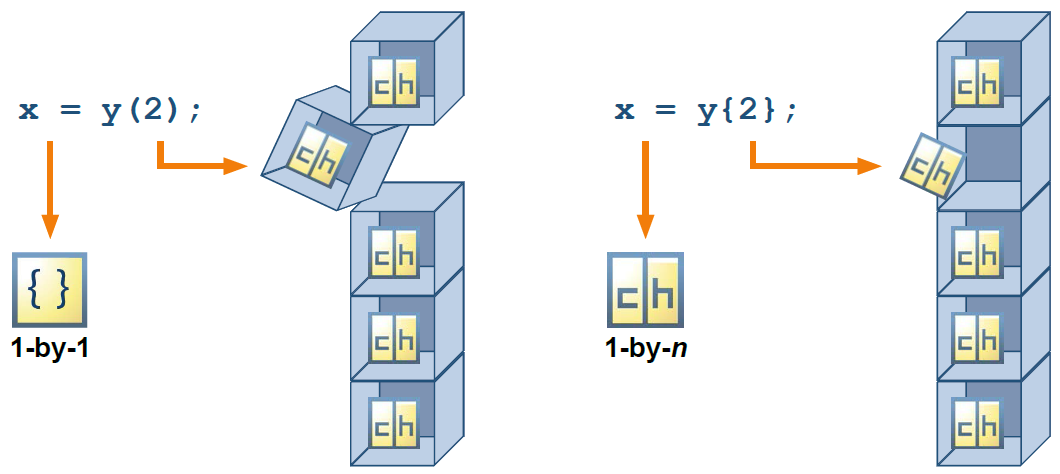

*Tomado de la documentación oficial de MATLAB.*

**Aclaración:** Figura utilizada originalmente para explicar la diferencia entre paréntesis `()` y llaves `{}` de esta indexación en arreglos celda, aunque el funcionamiento es el mismo para arreglos tabla.

whos patientesTb1

  Name                Size            Bytes  Class    Attributes

  patientesTb1      100x4             29079  table              



patientesTb1(1,1)
patientesTb1(1,"Edad") %parentesos
patientesTb1{1,"Edad"}%llaves

ans = 38

### Indexación utilizando los nombres de las variables

Cuando se indexa a través de la notación punto, hay dos formas de especificar una variable.

- **Por nombre, sin comillas.** Por ejemplo, `T.Nombres`.

- **Por una expresión, donde la expresión está encerrada entre paréntesis después del punto.** Por ejemplo, `T.("Fecha de inicio")`.

Se utiliza la primera sintaxis cuando el nombre de una variable tabular también es un identificador válido de MATLAB. Es decir, cuando el nombre de la variable sigue las reglas para nombrar variables dentro de MATLAB (letras, números y guión bajo).

**Figura 6.** Indexación de una tabla.

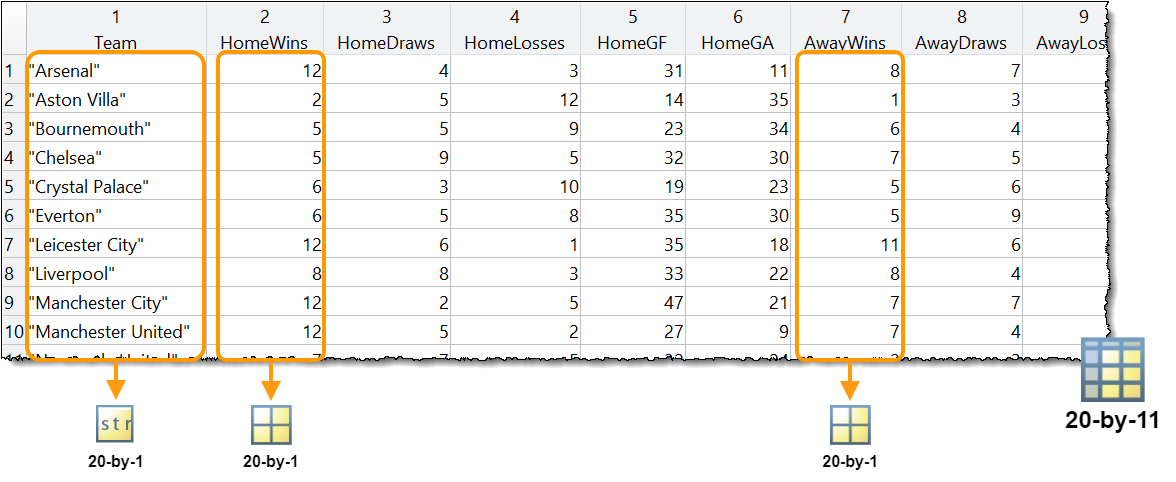

*Tomado de la documentación oficial de MATLAB.*

Por otra parte, se utiliza la segunda sintaxis cuando se especifica:

- Un número que indica la posición de la variable en la tabla.

- Un nombre de variable que no es un identificador válido de MATLAB.

- Cuando se agregan variables con identificadores no válidos de MATLAB.

El resultado de la indexación utilizando la notación punto tiene el **mismo tipo de dato** que la variable indexada. Esto se debe a que esta indexación extrae el contenido de la variable.

disp(patientesTb1)

      Apellidos       Edad    Altura              Localidad          
    ______________    ____    ______    _____________________________

    {'Smith'     }     38       71      {'County General Hospital'  }
    {'Johnson'   }     43       69      {'VA Hospital'              }
    {'Williams'  }     38       64      {'St. Mary's Medical Center'}
    {'Jones'     }     40       67      {'VA Hospital'              }
    {'Brown'     }     49       64      {'County General Hospital'  }
    {'Davis'     }     46       68      {'St. Mary's Medical Center'}
    {'Miller'    }     33       64      {'VA Hospital'              }
    {'Wilson'    }     40       68      {'VA Hospital'              }
    {'Moore'     }     28       68      {'St. Mary's Medical Center'}
    {'Taylor'    }     31       66      {'County General Hospital'  }
    {'Anderson'  }     

patientesTb1.("Apellidos")

ans = 100×1 cell array
    {'Smith'    }
    {'Johnson'  }
    {'Williams' }
    {'Jones'    }
    {'Brown'    }
    {'Davis'    }
    {'Miller'   }
    {'Wilson'   }
    {'Moore'    }
    {'Taylor'   }
    {'Anderson' }
    {'Thomas'   }
    {'Jackson'  }
    {'White'    }
    {'Harris'   }
    {'Martin'   }
    {'Thompson' }
    {'Garcia'   }
    {'Martinez' }
    {'Robinson' }
    {'Clark'    }
    {'Rodriguez'}
    {'Lewis'    }
    {'Lee'      }
    {'Walker'   }
    {'Hall'     }
    {'Allen'    }
    {'Young'    }
    {'Hernandez'}
    {'King'     }


### Combinar indexaciones

En ocasiones resulta conveniente trabajar con ambas indexaciones (utilizando nombres de variables y por posición) al mismo tiempo. Por lo tanto, se debe utilizar paréntesis en la indexación utilizando nombres de variables y a partir de ahí se puede indexar por posición.

load patients.mat
whos

  Name                            Size            Bytes  Class      Attributes

  Age                           100x1               800  double               
  Diastolic                     100x1               800  double               
  Gender                        100x1             11412  cell                 
  Height                        100x1               800  double               
  LastName                      100x1             11616  cell                 
  Location                      100x1             14208  cell                 
  SelfAssessedHealthStatus      100x1             11540  cell                 
  Smoker                        100x1               100  logical              
  Systolic                      100x1               800  double               
  Weight                        100x1               800  double               
  ans                           100x1             11616  cell                 
  array2table                    10x20             

patientesTb1=table(LastName,Gender,Height)

patientesTb1 = 100×3 table
      LastName        Gender      Height
    ____________    __________    ______

    {'Smith'   }    {'Male'  }      71  
    {'Johnson' }    {'Male'  }      69  
    {'Williams'}    {'Female'}      64  
    {'Jones'   }    {'Female'}      67  
    {'Brown'   }    {'Female'}      64  
    {'Davis'   }    {'Female'}      68  
    {'Miller'  }    {'Female'}      64  
    {'Wilson'  }    {'Male'  }      68  
    {'Moore'   }    {'Male'  }      68  
    {'Taylor'  }    {'Female'}      66  
    {'Anderson'}    {'Female'}      68  
    {'Thomas'  }    {'Female'}      66  
    {'Jackson' }    {'Male'  }      71  
    {'White'   }    {'Male'  }      72  
    {'Harris'  }    {'Female'}      65  
    {'Martin'  }    {'Male'  }      71  


head(patientesTb1)

      LastName        Gender      Height
    ____________    __________    ______

    {'Smith'   }    {'Male'  }      71  
    {'Johnson' }    {'Male'  }      69  
    {'Williams'}    {'Female'}      64  
    {'Jones'   }    {'Female'}      67  
    {'Brown'   }    {'Female'}      64  
    {'Davis'   }    {'Female'}      68  
    {'Miller'  }    {'Female'}      64  
    {'Wilson'  }    {'Male'  }      68  



patientesTb1.Height(1:10)

ans =     71
    69
    64
    67
    64
    68
    64
    68
    68
    66


### Agregar/quitar variables a una tabla

Existen diferentes formas para agregar una variable a una tabla, pero la más común es utilizar la notación punto.

load patients.mat

patientesTb1.("Genero")=Gender

patientesTb1 = 100×5 table
      LastName        Gender      Height      Gnero         Genero  
    ____________    __________    ______    __________    __________

    {'Smith'   }    {'Male'  }      71      {'Male'  }    {'Male'  }
    {'Johnson' }    {'Male'  }      69      {'Male'  }    {'Male'  }
    {'Williams'}    {'Female'}      64      {'Female'}    {'Female'}
    {'Jones'   }    {'Female'}      67      {'Female'}    {'Female'}
    {'Brown'   }    {'Female'}      64      {'Female'}    {'Female'}
    {'Davis'   }    {'Female'}      68      {'Female'}    {'Female'}
    {'Miller'  }    {'Female'}      64      {'Female'}    {'Female'}
    {'Wilson'  }    {'Male'  }      68      {'Male'  }    {'Male'  }
    {'Moore'   }    {'Male'  }      68      {'Male'  }    {'Male'  }
    {'Taylor'  }    {'Female'}      66     

Por otra parte, para quitar una variable de la tabla también se utiliza la notación punto, indexando la variable que se desea eliminar y asignándole la matriz vacía.

patientesTb1.("Gender")=[]

patientesTb1 = 100×4 table
      LastName      Height      Gnero         Genero  
    ____________    ______    __________    __________

    {'Smith'   }      71      {'Male'  }    {'Male'  }
    {'Johnson' }      69      {'Male'  }    {'Male'  }
    {'Williams'}      64      {'Female'}    {'Female'}
    {'Jones'   }      67      {'Female'}    {'Female'}
    {'Brown'   }      64      {'Female'}    {'Female'}
    {'Davis'   }      68      {'Female'}    {'Female'}
    {'Miller'  }      64      {'Female'}    {'Female'}
    {'Wilson'  }      68      {'Male'  }    {'Male'  }
    {'Moore'   }      68      {'Male'  }    {'Male'  }
    {'Taylor'  }      66      {'Female'}    {'Female'}
    {'Anderson'}      68      {'Female'}    {'Female'}
    {'Thomas'  }      66      {'Female'}    {'Female'}
    {'Jackson' }      71      {'Male'  }    {'Male'  }
    {'White

## Funciones para trabajar con tablas

Existen diversas funciones que están diseñadas para trabajar con tablas, así que a continuación se detallan las más usuales.

### Funciones `width` y `height`

Para conocer el número de variables (o columnas) de una tabla se utiliza la función `width`, mientras que para conocer el número de observaciones (o filas) se utiliza la función `height`.

Es decir, en lugar de utilizar la función `size` o `length` para determinar las dimensiones de una tabla, se utilizan las funciones previamente mencionadas, aunque es posible utilizar estas últimas sin ningún problema.

patientesTb1

patientesTb1 = 100×4 table
      LastName      Height      Gnero         Genero  
    ____________    ______    __________    __________

    {'Smith'   }      71      {'Male'  }    {'Male'  }
    {'Johnson' }      69      {'Male'  }    {'Male'  }
    {'Williams'}      64      {'Female'}    {'Female'}
    {'Jones'   }      67      {'Female'}    {'Female'}
    {'Brown'   }      64      {'Female'}    {'Female'}
    {'Davis'   }      68      {'Female'}    {'Female'}
    {'Miller'  }      64      {'Female'}    {'Female'}
    {'Wilson'  }      68      {'Male'  }    {'Male'  }
    {'Moore'   }      68      {'Male'  }    {'Male'  }
    {'Taylor'  }      66      {'Female'}    {'Female'}
    {'Anderson'}      68      {'Female'}    {'Female'}
    {'Thomas'  }      66      {'Female'}    {'Female'}
    {'Jackson' }      71      {'Male'  }    {'Male'  }
    {'White

width(patientesTb1)

ans = 4

height(patientesTb1)

ans = 100

### Funciones `head` y `tail`

La función `head` permite visualizar las *k-ésimas* primeras observaciones. Por defecto $k$ es igual a 8.

head(patientesTb1)

      LastName      Height      Gnero         Genero  
    ____________    ______    __________    __________

    {'Smith'   }      71      {'Male'  }    {'Male'  }
    {'Johnson' }      69      {'Male'  }    {'Male'  }
    {'Williams'}      64      {'Female'}    {'Female'}
    {'Jones'   }      67      {'Female'}    {'Female'}
    {'Brown'   }      64      {'Female'}    {'Female'}
    {'Davis'   }      68      {'Female'}    {'Female'}
    {'Miller'  }      64      {'Female'}    {'Female'}
    {'Wilson'  }      68      {'Male'  }    {'Male'  }



Evidentemente la función `head` mostrará las primeras 8 observaciones siempre que la tabla las tenga, caso contrario mostrará todas las que haya.

Por otra parte, la función `tail` permite visualizar las últimas *k-ésimas* observaciones. Por defecto $k$ es igual a 8.

tail(patientesTb1,3)

     LastName      Height     Gnero       Genero 
    ___________    ______    ________    ________

    {'Griffin'}      70      {'Male'}    {'Male'}
    {'Diaz'   }      68      {'Male'}    {'Male'}
    {'Hayes'  }      66      {'Male'}    {'Male'}



Al igual que la función `head`, la función `tail` mostrará las últimas 8 observaciones siempre que la tabla las tenga, caso contrario mostrará todas las que haya.

### Función `movevars`

La función `movevars` permite mover las variables de una tabla. A continuación se muestra una imagen de cómo se realiza esto.

**Figura 7.** Visualización de cómo trabaja la función `movevars`.

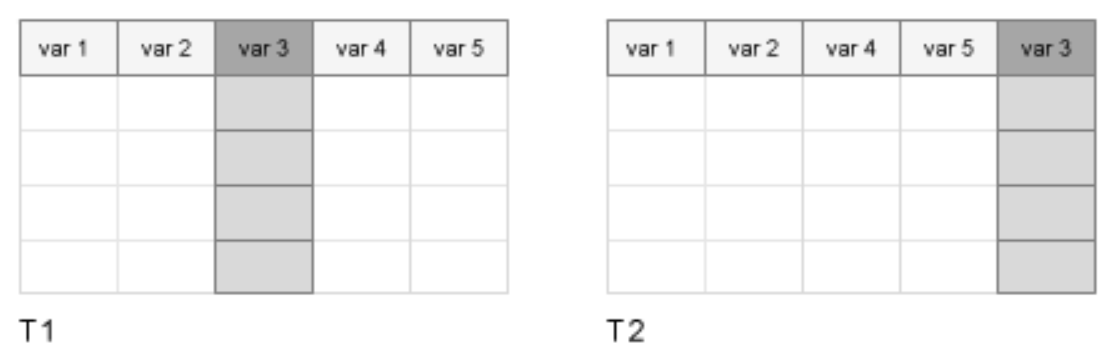

*Tomado de la documentación oficial de MATLAB.*

`A continuación se muestra un ejemplo de esto.`

patientesTb1

patientesTb1 = 100×4 table
      LastName      Height      Gnero         Genero  
    ____________    ______    __________    __________

    {'Smith'   }      71      {'Male'  }    {'Male'  }
    {'Johnson' }      69      {'Male'  }    {'Male'  }
    {'Williams'}      64      {'Female'}    {'Female'}
    {'Jones'   }      67      {'Female'}    {'Female'}
    {'Brown'   }      64      {'Female'}    {'Female'}
    {'Davis'   }      68      {'Female'}    {'Female'}
    {'Miller'  }      64      {'Female'}    {'Female'}
    {'Wilson'  }      68      {'Male'  }    {'Male'  }
    {'Moore'   }      68      {'Male'  }    {'Male'  }
    {'Taylor'  }      66      {'Female'}    {'Female'}
    {'Anderson'}      68      {'Female'}    {'Female'}
    {'Thomas'  }      66      {'Female'}    {'Female'}
    {'Jackson' }      71      {'Male'  }    {'Male'  }
    {'White

patientesTb1=movevars(patientesTb1,["Genero"],"Before","Height")

patientesTb1 = 100×4 table
      LastName        Genero      Height      Gnero   
    ____________    __________    ______    __________

    {'Smith'   }    {'Male'  }      71      {'Male'  }
    {'Johnson' }    {'Male'  }      69      {'Male'  }
    {'Williams'}    {'Female'}      64      {'Female'}
    {'Jones'   }    {'Female'}      67      {'Female'}
    {'Brown'   }    {'Female'}      64      {'Female'}
    {'Davis'   }    {'Female'}      68      {'Female'}
    {'Miller'  }    {'Female'}      64      {'Female'}
    {'Wilson'  }    {'Male'  }      68      {'Male'  }
    {'Moore'   }    {'Male'  }      68      {'Male'  }
    {'Taylor'  }    {'Female'}      66      {'Female'}
    {'Anderson'}    {'Female'}      68      {'Female'}
    {'Thomas'  }    {'Female'}      66      {'Female'}
    {'Jackson' }    {'Male'  }      71      {'Male'  }
    {'White

## Realizar cálculos con tablas

Hasta este momento se ha realizado diferentes ejercicios y ejemplos utilizando funciones para clases numéricas (enteros y decimales), arreglos cadena y arreglos caracter, y para valores lógicos.

Ahora bien, en una tabla es posible reasignar a una variable la misma variable modificada (aplicando algún cálculo, función, etc.), o simplemente creando una variable a partir de otras.

### Ejercicio

Determinar el índice de masa corporal (IMC) para los pacientes del archivo `patients.mat`.

Recordar que el IMC se detemina como


$$\textrm{IMC}=\frac{m}{h^2 }$$


donde $m$ es la masa, en kilogramos, y $h$ es la altura, en metros.

### Solución

clc
clear
load patients.mat LastName Weight Height
whos

  Name            Size            Bytes  Class     Attributes

  Height        100x1               800  double              
  LastName      100x1             11616  cell                
  Weight        100x1               800  double              



T=table(string(LastName),Weight,Height)

T = 100×3 table
       Var1       Weight    Height
    __________    ______    ______

    "Smith"        176        71  
    "Johnson"      163        69  
    "Williams"     131        64  
    "Jones"        133        67  
    "Brown"        119        64  
    "Davis"        142        68  
    "Miller"       142        64  
    "Wilson"       180        68  
    "Moore"        183        68  
    "Taylor"       132        66  
    "Anderson"     128        68  
    "Thomas"       137        66  
    "Jackson"      174        71  
    "White"        202        72  
    "Harris"       129        65  
    "Martin"       181        71  


T.Weight=T.Weight/2.2;
T.Height=T.Height/39.37;
head(T)

       Var1       Weight    Height
    __________    ______    ______

    "Smith"           80    1.8034
    "Johnson"     74.091    1.7526
    "Williams"    59.545    1.6256
    "Jones"       60.455    1.7018
    "Brown"       54.091    1.6256
    "Davis"       64.545    1.7272
    "Miller"      64.545    1.6256
    "Wilson"      81.818    1.7272



T.IMC=T.Weight./(T.Height).^2

T = 100×4 table
       Var1       Weight    Height     IMC  
    __________    ______    ______    ______

    "Smith"           80    1.8034    24.598
    "Johnson"     74.091    1.7526    24.121
    "Williams"    59.545    1.6256    22.533
    "Jones"       60.455    1.7018    20.874
    "Brown"       54.091    1.6256    20.469
    "Davis"       64.545    1.7272    21.636
    "Miller"      64.545    1.6256    24.425
    "Wilson"      81.818    1.7272    27.426
    "Moore"       83.182    1.7272    27.883
    "Taylor"          60    1.6764     21.35
    "Anderson"    58.182    1.7272    19.503
    "Thomas"      62.273    1.6764    22.159
    "Jackson"     79.091    1.8034    24.319
    "White"       91.818    1.8288    27.453
    "Harris"      58.636     1.651    21.512
    "Martin"      82.273    1.8034    25.297


head(T)

       Var1       Weight    Height     IMC  
    __________    ______    ______    ______

    "Smith"           80    1.8034    24.598
    "Johnson"     74.091    1.7526    24.121
    "Williams"    59.545    1.6256    22.533
    "Jones"       60.455    1.7018    20.874
    "Brown"       54.091    1.6256    20.469
    "Davis"       64.545    1.7272    21.636
    "Miller"      64.545    1.6256    24.425
    "Wilson"      81.818    1.7272    27.426



## Material adicional

- [Tablas](https://www.mathworks.com/help/matlab/tables.html)

- [Ventajas de usar tablas](https://www.mathworks.com/help/matlab/matlab_prog/advantages-of-using-tables.html)

- [Crear tablas y asignarles información](https://www.mathworks.com/help/matlab/matlab_prog/create-a-table.html)

- [Acceder a información de una tabla](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html)

- [Agregar, eliminar y reorganizar variables de tabla](https://www.mathworks.com/help/matlab/matlab_prog/add-and-delete-table-variables.html)

- [Cálculos en tablas](https://www.mathworks.com/help/matlab/matlab_prog/calculations-on-tables.html)

- [Modificar unidades, descripciones y nombres de variables de tabla](https://www.mathworks.com/help/matlab/matlab_prog/modify-units-descriptions-and-table-variable-names.html)

- [Conjuntos de datos de muestra](https://www.mathworks.com/help/stats/sample-data-sets.html)